clear
clc
num_samples = 1000;
true_gamma = 0.5; 
delta = normrnd(0,1,[1,num_samples]);

**Generate the true state sequence z's and the observation sequence x's**

% GENERATE true underlying state sequence z
z0 = 1000;
true_z = zeros(1, num_samples) ;
true_z(1) = true_gamma*z0 + delta(1);
for i=2:num_samples
    true_z(i) = true_gamma*true_z(i-1) + delta(i);
end
% GENERATE x
true_x = zeros(1, num_samples);
for i=1:num_samples
    % normal distribution (z, 1)
    true_x(i) = normrnd(true_z(i),1);
end

**Initialization:** Given x, find x - mean(x) and initialize random gamma.

% move mean x to 0 
mean_true_x = mean(true_x)

mean_true_x = 1.0455


x = zeros(1, num_samples);
for i=1:num_samples
    x(i) = (true_x(i) - mean_true_x);
end
gamma = rand;
% gamma is non zero
while(gamma == 0)
    gamma = rand;
end

**Repeat until covergence:**

**Step 1:** Given z, z_0 = 0 and \gamma, we adjust z to minimize the variance of y and w

**Step 2:** Given x, z, using the poor man procedure, we adjust  \gamma to minimize mean of y and w.

threshold = 0.000000001;
all_MSE = zeros(1, 0);
cnt = 0;
while (true)
    cnt = cnt+1;
    
    % STEP 1
    % calculate A, c in Az = c
    u = -2 * gamma;
    v = 4 + 2 * gamma^2;
    c = zeros(1, num_samples);
    for i=1:num_samples
        c(i) = 2*x(i);
    end
    
    % calculate LU decomposition of A
    r = zeros(1, num_samples);
    t = zeros(1, num_samples);
    
    t(1) = v;
    for i=2:num_samples
        r(i) = u/t(i-1);
        if i < num_samples
            t(i) = v - r(i)*u ;
        else t(i) = 4 - r(i)*u ;
        end
    end
    
    % calculate z
    % Az = LUz = C. Let Uz = D => LD = C 
    % Calculate D
    d = zeros(1, num_samples);
    d(1) = c(1);
    
    for i=2:num_samples
        d(i) = c(i) - r(i)*d(i-1);
    end
    % Calculate Z
    curr_z = zeros(1, num_samples);
    curr_z(num_samples) = d(num_samples)/t(num_samples);
    for i = num_samples-1:-1:1
       curr_z(i) = (d(i) - u*curr_z(i+1))/t(i);
    end
    curr_z = curr_z + mean_true_x;
    if cnt > 1
        error = abs(z-curr_z).^2;
        MSE = sum(error(:)) / num_samples;
        all_MSE = [all_MSE MSE];
    end
    z = curr_z;
    
    % STEP 2
    % calcualte gamma
    z_prev = zeros(1, num_samples);
    z_prev(1) = z0;
    for i=2:num_samples
        z_prev(i) = z(i-1);
    end
    
    gamma = sum(z)/sum(z_prev);
    if cnt > 1 && MSE < threshold
        break
    end
end
found_gamma = gamma

found_gamma = 0.4855

% mean of z
mean(z);
% Compare with the true z
real_error = abs(z-true_z).^2;
real_MSE = sum(real_error(:)) / num_samples

real_MSE = 58.3988

saveas(figure(1),'factor_discovery_uniform_dist_trueplot.png');
saveas(figure(2),'factor_discovery_uniform_dist_estimatedplot.png');

true_z_prev = zeros(1, num_samples)

true_z_prev =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


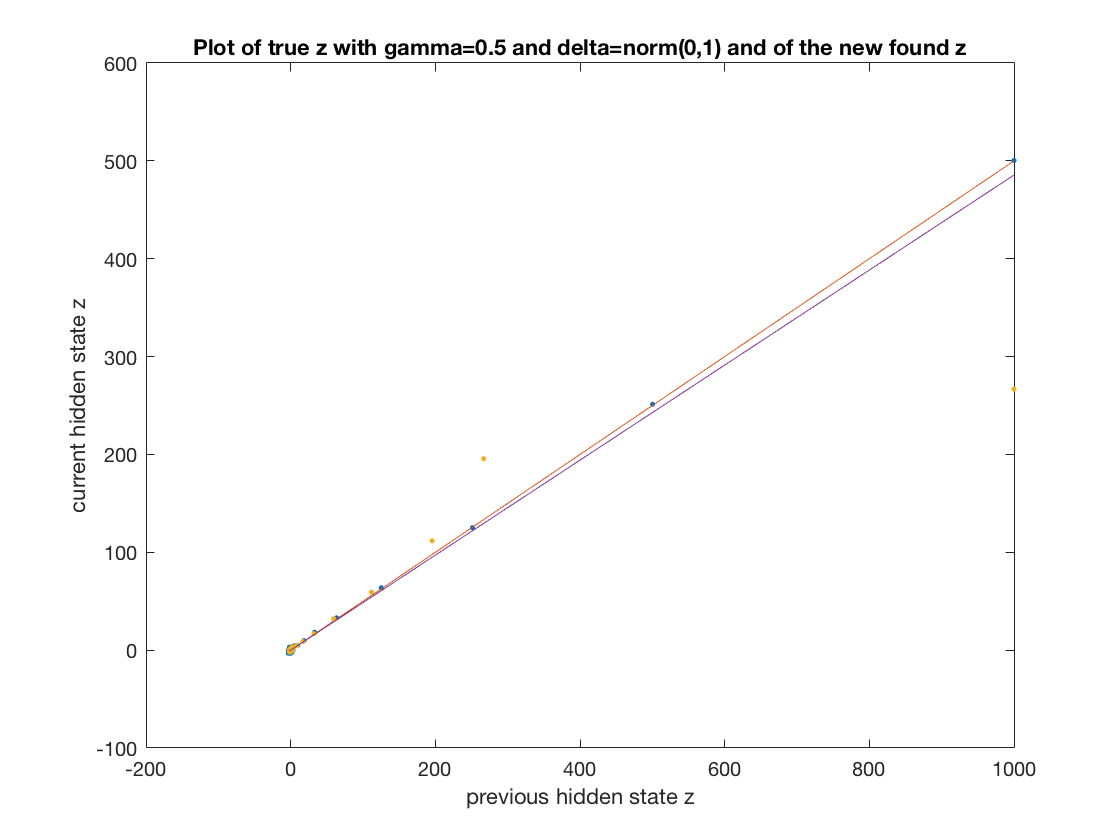

true_z_prev(1) = z0;
for i=2:num_samples
    true_z_prev(i) = true_z(i-1);
end

% plot true_z and true_z_prev
figure(4)
plot(true_z_prev, true_z, '.');
title("Plot of true z with gamma=0.5 and delta=norm(0,1) and of the new found z")
xlabel('previous hidden state z')
ylabel('current hidden state z')
hold on
true_z_hat = (true_z_prev*true_gamma)';
plot(true_z_prev, true_z_hat);
hold on
plot(z_prev, z, '.');
hold on
z_hat = (z_prev*found_gamma)';
plot(z_prev, z_hat);

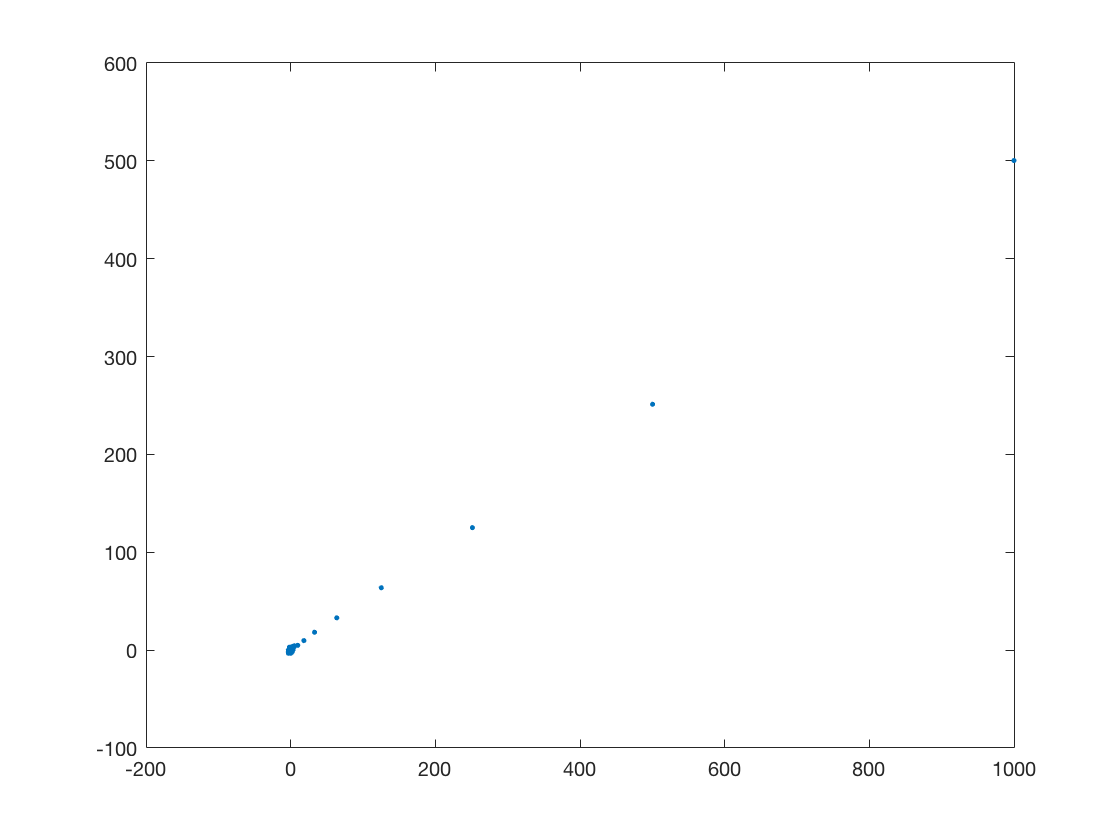


figure(11)
title("true z, gamma = 0.5, delta = norm(0,1)")
plot(true_z_prev, true_z, '.');

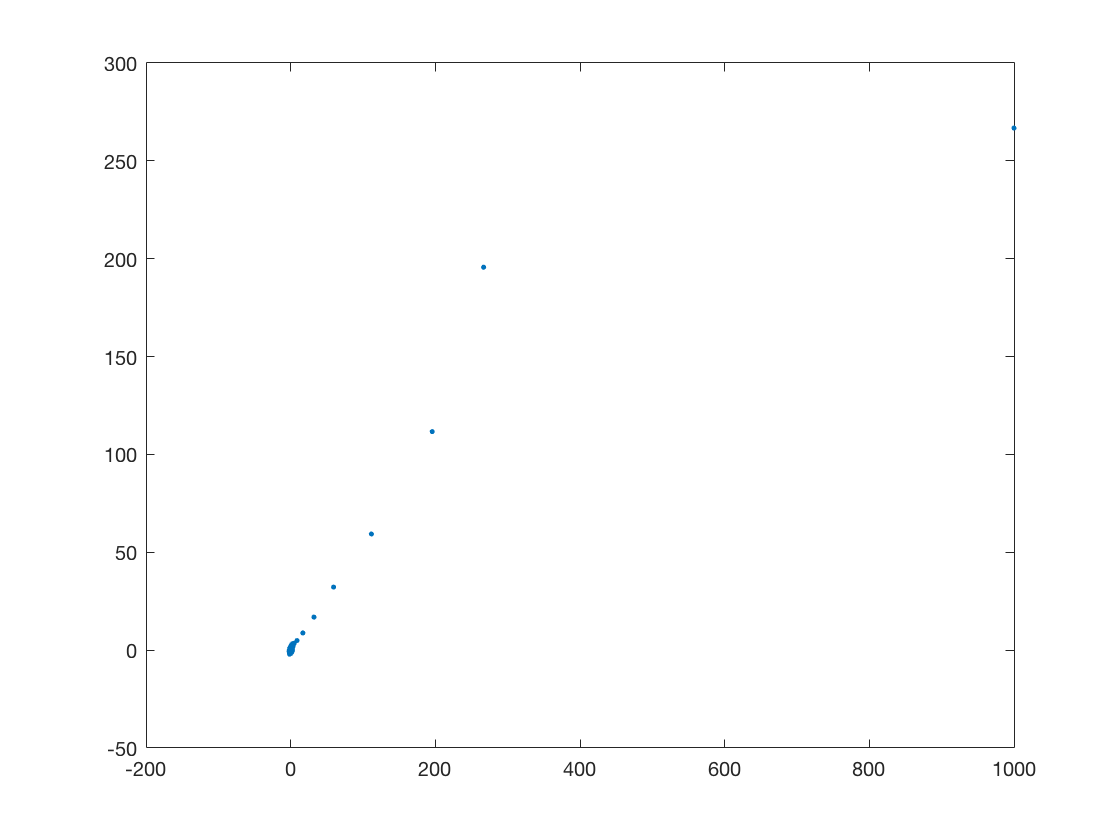


figure(12)
title("found z, found_gamma, delta = 0")
plot(z_prev, z, '.');

% calculate w
w = (z * z') \ (z * true_z')

w = 1.5872

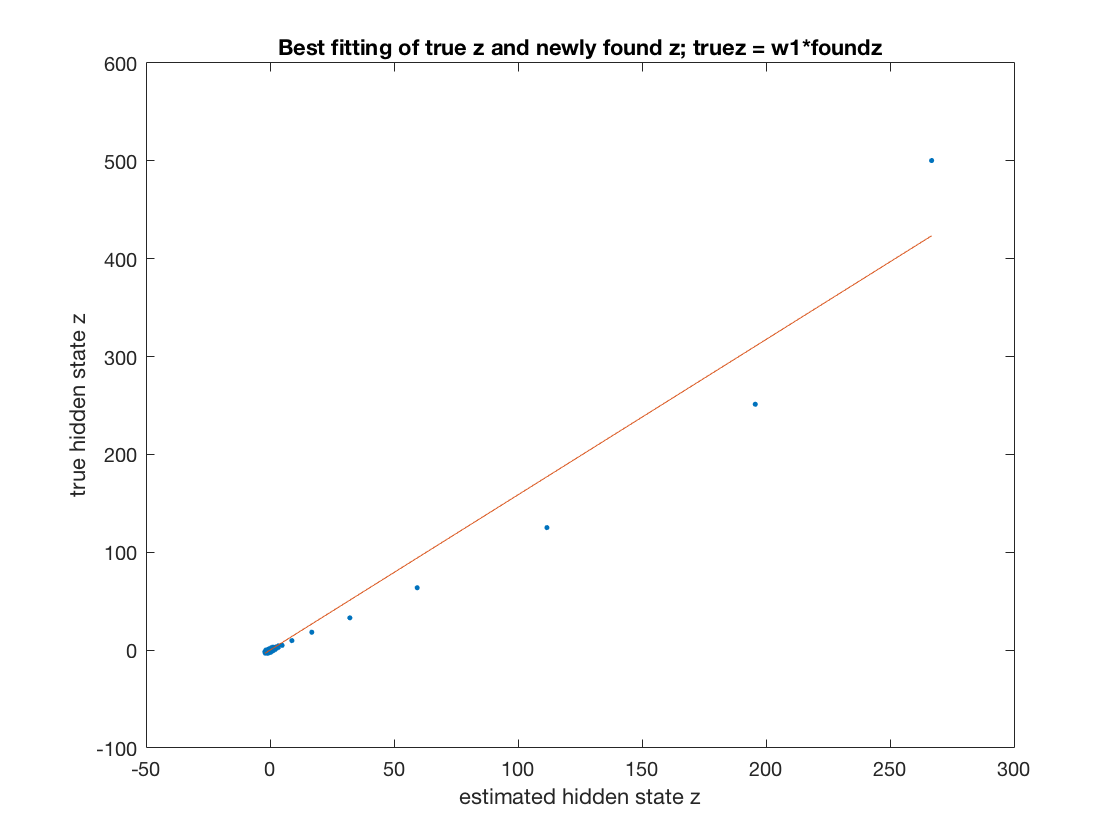


% plot true_z and estimated z
figure(6)
plot(z, true_z, '.');
title("Best fitting of true z and newly found z; truez = w1*foundz")
xlabel('estimated hidden state z')
ylabel('true hidden state z')
hold on
plot(z, (z*w)');